# Lysosome Stats

Use this script to generate the figures presented in the manuscript. 

Requires the following variables to be loaded:

## Load Variables

Change directory to the Lysosome Analysis Folder 

clearvars -except paths proj
close all
clc
[VL, idT, cellT, dyingT,lysT] = loadProjectTables(paths);
idT = sortrows(idT,["Type", "Health"])

idT = 34×8 table
               Cell                Type             Lysosome               Health      TasteBud      Source      Dataset        Folder     
    ___________________________    ____    ___________________________    _________    ________    __________    _______    _______________

    "TB1_AP16_EM"                  "I"     "TB1_AP16__LYS_RSL"            "healthy"     "TB1"      "Rob"         "TF21"     "ROB_TF21_TB1" 
    "TB1_AP34_EM"                  "I"     "TB1_AP34_lys_RSL"             "healthy"     "TB1"      "Rob"         "TF21"     "ROB_TF21_TB1" 
    "TB1_AP36_EM"                  "I"     "TB1_AP36_LYS_RSL"             "healthy"     "TB1"      "Rob"         "TF21"     "ROB_TF21_TB1" 
    "TB1_A

### Examine Lysosome Volume Distributions

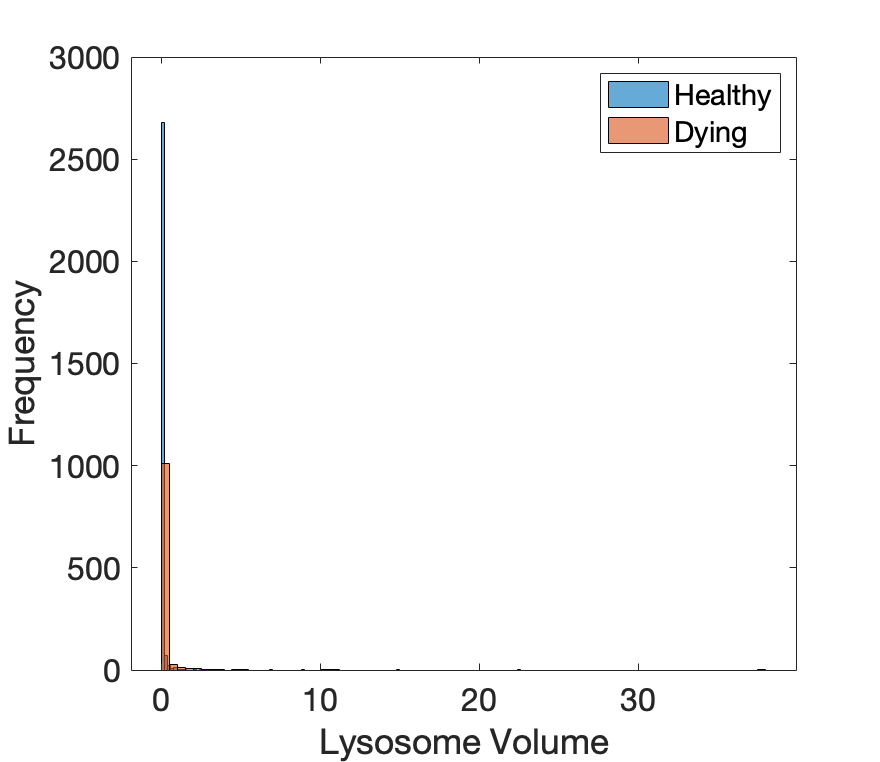

mmfig; 
la = lysT.Health =="healthy";
histogram(lysT.Volume(la))

hold on
histogram(lysT.Volume(~la))
ylabel('Frequency')
xlabel('Lysosome Volume')
legend('Healthy','Dying')

- volumes appear highly skewed

#### Examine Mean and Medians

groupsummary(lysT,"Health",["mean" "median" "std"],"Volume")

ans = 3×5 table
    Health     GroupCount    mean_Volume    median_Volume    std_Volume
    _______    __________    ___________    _____________    __________

    early          795          0.2547         0.027787        1.5429  
    healthy       2811        0.074672        0.0090638       0.62922  
    late           277        0.042787        0.0033905       0.16259  


- large differences between Mean and Median values further confirm non-normality

gs = groupsummary(lysT,"Health",{@skewness, @kurtosis},"Volume");
gs.Properties.VariableNames(3:4) = {'Skewness','Kurtosis'}

gs = 3×4 table
    Health     GroupCount    Skewness    Kurtosis
    _______    __________    ________    ________

    early          795        19.358      448.26 
    healthy       2811        24.753      741.53 
    late           277        9.2099      104.02 


- volumes are highly skewed 

#### One-sample Kolmogorov-Smirnov test for normality of lysosomal volumes in each cell

h=1 means not normal

warning off
for n=unique(lysT.Cell)'

    x = lysT.Volume(lysT.Cell==n);
    if numel(x)>3
        [h, p] = kstest(x);     
        fprintf('%s: h = %d, p=%1.2f\n',n,h,p)       
    end
end

TB1_AP02_EM: h = 1, p=0.00
TB1_AP13_EM: h = 1, p=0.00
TB1_AP14_EM: h = 1, p=0.00
TB1_AP16_EM: h = 1, p=0.00
TB1_AP31_EM: h = 1, p=0.00
TB1_AP34_EM: h = 1, p=0.00
TB1_AP36_EM: h = 1, p=0.00
TB1_AP37_EM: h = 1, p=0.00
TB1_AP38_EM: h = 1, p=0.00
TB1_AP40_EM: h = 1, p=0.00
TB1_AP44_EM: h = 1, p=0.00
TB1_AP51_EM: h = 1, p=0.00
TB1_AP70_RSL: h = 1, p=0.00
TB1_IMMCell09_CM_ry: h = 1, p=0.00
TB1_IMMcell08_CM_RKJ: h = 1, p=0.00
TB2 Nucleus_04_cw_cell-ry: h = 1, p=0.00
TB2_T1C-05_cw: h = 1, p=0.00
TB2_T1C-06_cw: h = 1, p=0.00
TB2_T2C-01_FR: h = 1, p=0.00
TB2_T2C-03_cw: h = 1, p=0.00
TB2_T2C-09_cw: h = 1, p=0.00
TB2_T2C-10_cw: h = 1, p=0.00
TB2_T2C-12_cw: h = 1, p=0.00
TB2_T2Cell03_CM_LES: h = 1, p=0.00
TB2_T3C-08_cw: h = 1, p=0.00
TB2_T3C-14_FR: h = 1, p=0.00
TB2_T3C-17_cw: h = 1, p=0.00
TB2_T3Cell07_cm_RSL: h = 1, p=0.00
TB2_T4C-01_cw: h = 1, p=0.00
TB2_TCdying-01_cw: h = 1, p=0.00
TB2_TCdying-02_cw: h = 1, p=0.00
TB2_t3cell02_CM_RSL: h = 1, p=0.00


warning on

even per cell, volumes are not normal

### Largest Lysosome Volumes

[m,idc] = maxk(lysT.Volume,10)

m =        37.765
       22.511
       14.934
       11.072
       10.743
       10.624
       10.067
        8.801
       6.9934
       5.4307


idc =         3883
        3882
        3881
        3880
        3879
        3878
        3877
        3876
        3875
        3874


lysT.Object(idc)

ans = 10×1 string array
    "TB1_AP13_RSL_LYS"
    "TB1_AP16__LYS_RSL"
    "TB1_AP38_lys_RSL"
    "TB1_AP34_lys_RSL"
    "TB1_AP40_RSL_LYS"
    "TB2_T2C-03_cw-lyso-ry"
    "TB1_AP13_RSL_LYS"
    "TB1_AP36_LYS_RSL"
    "TB1_AP36_LYS_RSL"
    "TB2_T2C-03_cw-lyso-ry"


### Calculate Lysosome Stats per cell

Calculate the stats of the lysosomes per cells. 

s = groupsummary(lysT,"Cell",["sum","median","mean","std","max","min"],"Volume");
s.Properties.VariableNames = {'Cell',...
    'LysCount', 'LysTotalVol','LysMedianVol','LysMeanVol','LysStdVol','LysMaxVol','LysMinVol'}

s = 34×8 table
               Cell                LysCount    LysTotalVol    LysMedianVol    LysMeanVol    LysStdVol    LysMaxVol    LysMinVol 
    ___________________________    ________    ___________    ____________    __________    _________    _________    __________

    "TB1_AP02_EM"                    214         6.2089        0.0090602       0.029013     0.066171      0.60227      0.0010142
    "TB1_AP13_EM"                    141         86.094         0.030512         0.6106       3.3254       37.765     1.2103e-05
    "TB1_AP14_EM"                    141         8.5901         0.021256       0.060923      0.11121      0.97239      9.504e-05
    "TB1_AP16_EM"                     65         32.149         0.0

manage cell names for cells that have apical "bits"

s.Cell = replace(s.Cell,"TB2_TCdying-01_cw","TB2_TCdying01"); % reconstruction includes "bits"
s.Cell = replace(s.Cell,"TB2_TCdying-02_cw","TB2_TCdying02");
s.Cell = replace(s.Cell,"TB3_TC01_dying_cw","TB3_TC01");

- **LysCount**: total number of lysosomes found in a cell

- **LysTotalVolume**: summed volume of all lysosomes found in a cell

- **LysMedianVol**: median volume of lysosomes found in a cell

- **LysTraceMedian**: The median cross-sectional area of a lysosome in a given cell

### Add percent volume

Percent volume is total lysosome volume divided by cell volume


$$\textrm{LysCellRatio}=\frac{\textrm{Total}\;\textrm{Lysosome}\;\textrm{Volume}\;}{\textrm{Cell}\;\textrm{Volume}}$$


cellT = join(cellT,s);
% cellT = sortrows(cellT,"Object");
cellT.LysCellRatio = cellT.LysTotalVol./ cellT.Volume

cellT = 34×16 table
               Cell                Type    Health     Volume    SurfaceArea      SAV                   Filename                 PlotSort    LysCount    LysTotalVol    LysMedianVol    LysMeanVol    LysStdVol    LysMaxVol    LysMinVol     LysCellRatio
    ___________________________    ____    _______    ______    ___________    _______    __________________________________    ________    ________    ___________    ____________    __________    _________    _________ 

- I and III healthy cells are about the same size

- I dying cell is larger than the other two cells

### Merge Dying Categories

cellT.Health = mergecats(cellT.Health,{'early','late'},'dying');
cellT.PlotSort = mergecats(cellT.PlotSort,{'ed','ld'},'d');

## Visualization

mmSetFigPublication

Default figure color set to white.
Default font size set to 16.0.

### Plot: Lysosome Count and Median Lysosome Volume

merge categories here

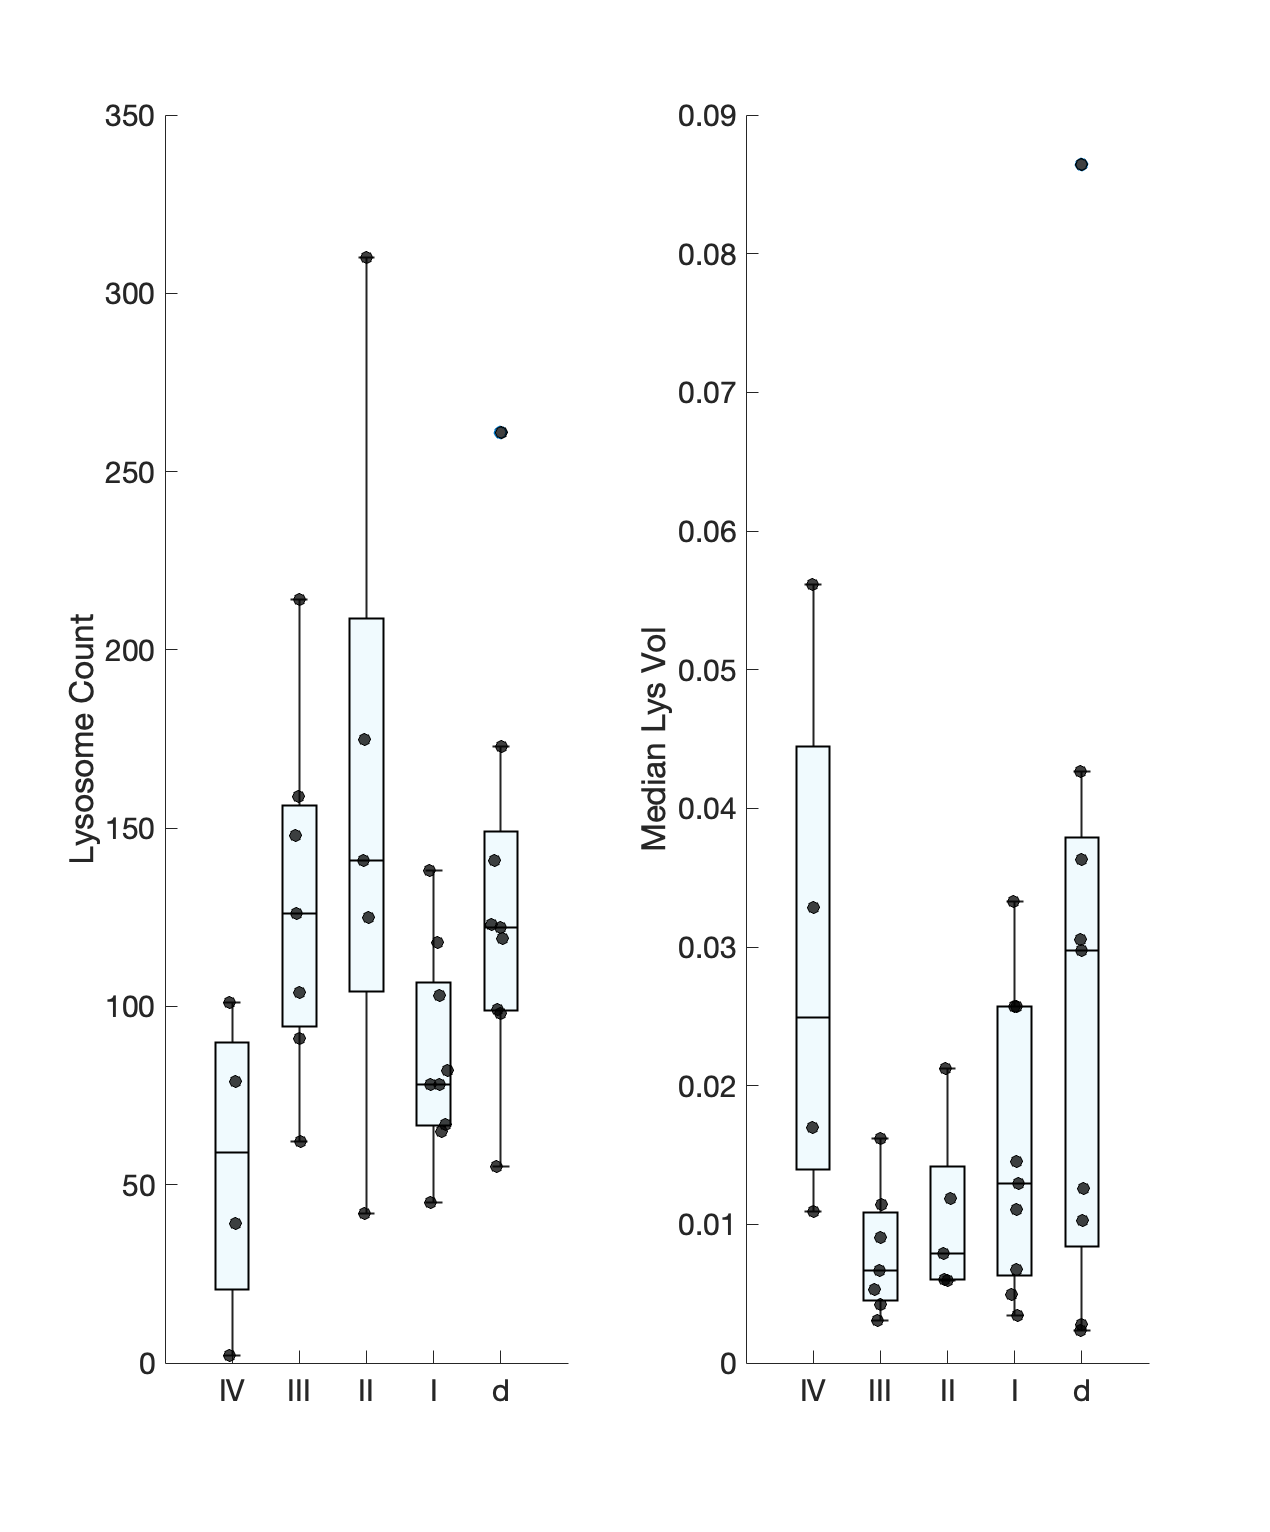

figure(Visible="on",Position=[1017 556 626 267],Color='white')

tiledlayout("horizontal")

% la = true(height(cellT),1);
% la = ~contains(cellT.Object,'AP37');
g = cellT.PlotSort;
y = cellT.LysCount;

y2 = cellT.LysMedianVol;
y2_label = ("Median Lys Vol");

% hb = boxchart(g,y,GroupByColor=g) % makes the box charts too skinny

nexttile
hold on
boxchart(g,y,BoxFaceColor="#b3e4fa",BoxEdgeColor='k')
swarmchart(g,y, ...
    MarkerFaceColor="k", ...
    MarkerFaceAlpha=0.75, ...
    MarkerEdgeColor="k", ...
    XJitterWidth=0.5)


ylabel("Lysosome Count")
xlabel("")
% grid on


nexttile
hold on

boxchart(g,y2,"BoxFaceColor","#b3e4fa",BoxEdgeColor='k')

swarmchart(g,y2, ...
    MarkerFaceColor="k", ...
    MarkerFaceAlpha=0.75, ...
    MarkerEdgeColor="k", ...
    XJitterWidth=0.25)

% xlabel("cell type")
% grid off

ylabel(y2_label)

colororder([])

## Focus on Type II Cells

Gardner Altman Plots

la = lysT.Health == "healthy" & lysT.Type == "II";
x = lysT.Volume(la);
la = lysT.Health == "early" & lysT.Type == "II";
y = lysT.Volume(la);

groupsummary(lysT(lysT.Type=="II",:),"Dying",["mean" "median"],"Volume")

ans = 2×4 table
     Dying     GroupCount    mean_Volume    median_Volume
    _______    __________    ___________    _____________

    healthy       793         0.042133        0.0084319  
    dying         697          0.25679         0.021478  


lysT.Dying = mergecats(lysT.Health,{'early','late'},'dying');
lysT.Dying = reordercats(lysT.Dying,{'healthy','dying'});

lysT = 3883×18 table
              Object               Health     Type    TasteBud    Dataset      Volume      SurfaceArea               Cell                SegmentLabel     TraceSum      TraceMax     TraceMean     TraceCount        verts         SAV      SizeLabel    PlotSort     Dying 
    ___________________________    _______    ____    ________    _______    __________    ___________    ___________________________    ____________    __________    __________    __________    

### Generate Swarmcharts

#### Display all data

figure(Visible="on",Position=[1376 523 260 280], Color='white');
hold on

la = lysT.Type == "II" & lysT.Dying == "healthy";
x = lysT.Dying(la);
y = lysT.Volume(la);
swarmchart(x,y,"filled",MarkerFaceAlpha=0.25)

la = lysT.Type == "II" & lysT.Dying == "dying";
x = lysT.Dying(la);
y = lysT.Volume(la);
swarmchart(x,y,"filled",MarkerFaceAlpha=0.25) 

colororder([validatecolor("#b3e4fa"); 0.3696	0	1.0000; ]) % Other blue #0072BD

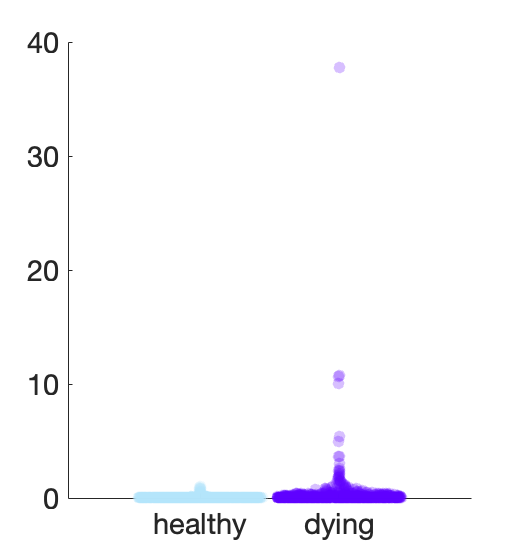

figure(Visible="on",Position=[1233 76 260 280], Color='white');

hold on

la = lysT.Type == "II" & lysT.Dying == "healthy";
x = lysT.Dying(la);
y = lysT.Volume(la);
swarmchart(x,y,"filled",MarkerFaceAlpha=0.25)
ylim([0 1]);

la = lysT.Type == "II" & lysT.Dying == "dying";
x = lysT.Dying(la);
y = lysT.Volume(la);
swarmchart(x,y,"filled",MarkerFaceAlpha=0.25) 
ylim([0 1]);

colororder([validatecolor("#b3e4fa"); 0.3696	0	1.0000; ])

scatter(categorical("healthy"),0.042133,100,'kd','filled')
scatter(categorical("dying"),0.25679,100,'kd','filled')

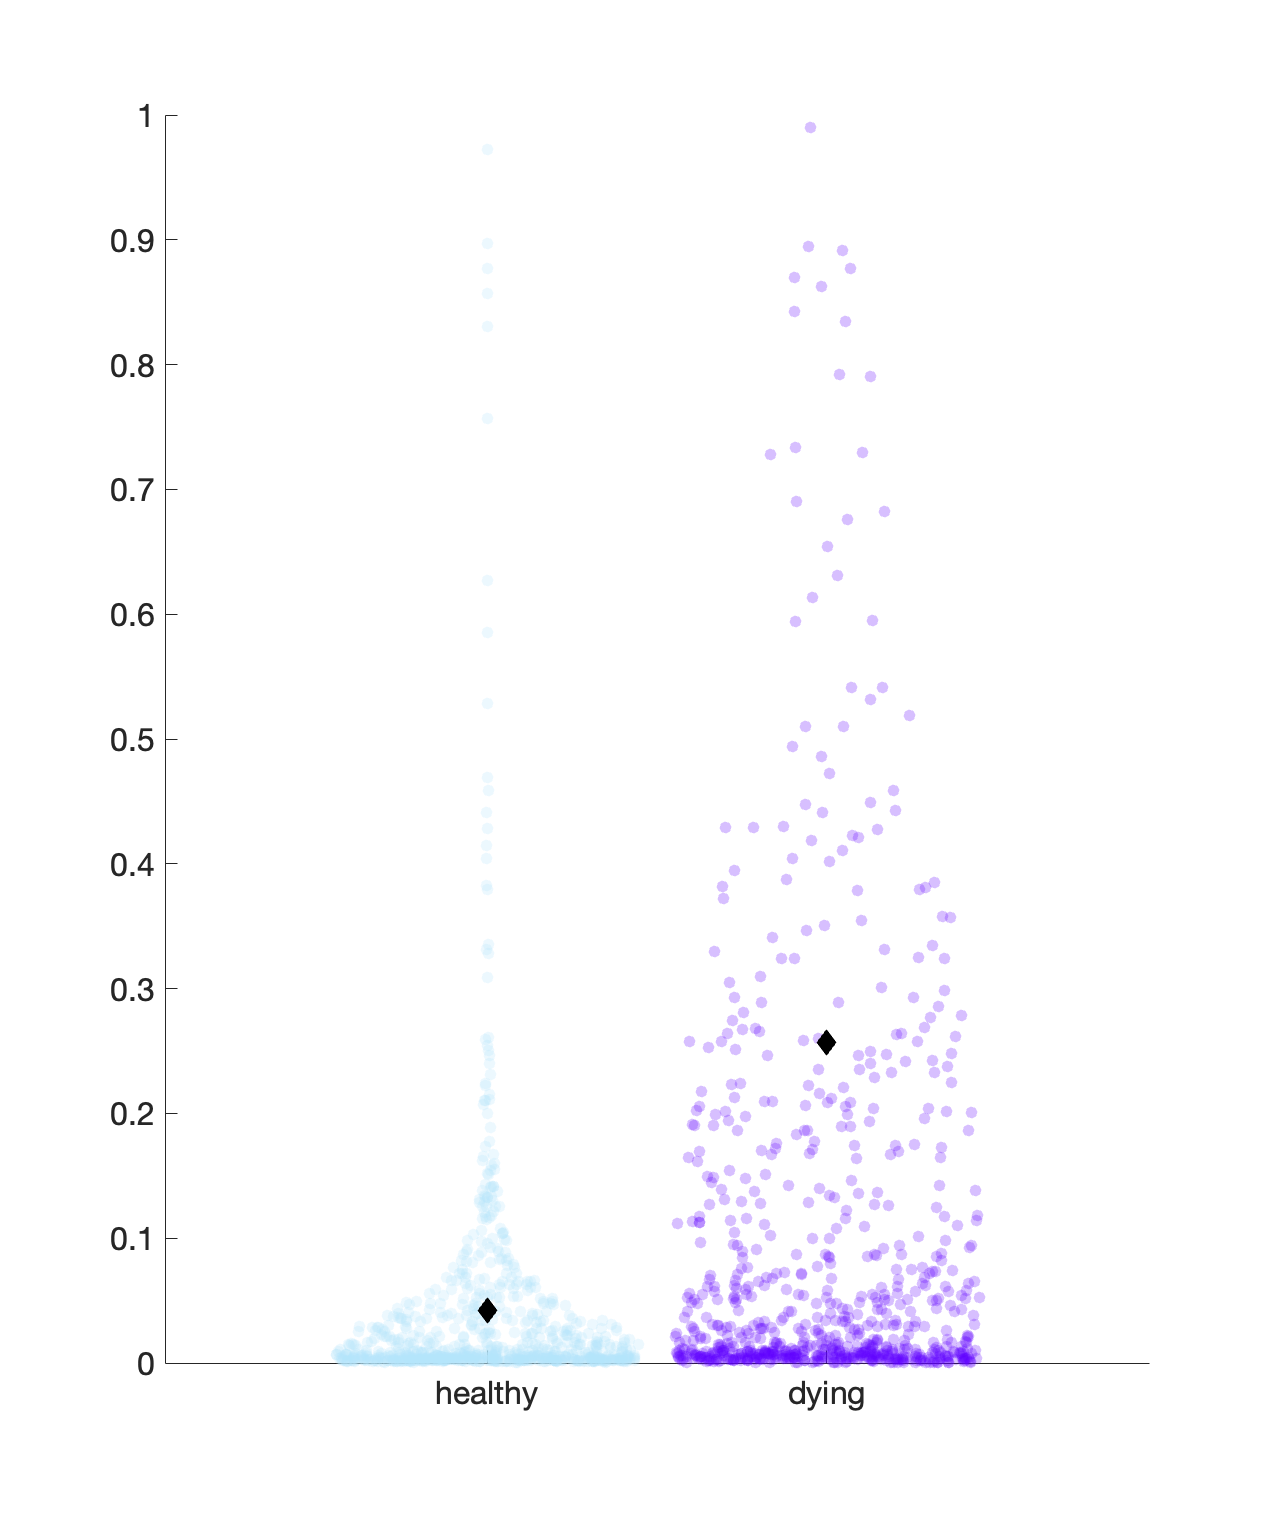

mmfig;


swarmchart(lysT(lysT.Type=="II",:),"Dying","Volume", ...
    "filled", ...
    MarkerFaceAlpha= 0.25,...
    XJitterWidth=1);
ylim([0 1]);

hold on
scatter(categorical("healthy"),0.042133,100,'kd','filled')
scatter(categorical("dying"),0.25679,100,'kd','filled')

#### mann-whitney

[p,h] = ranksum(x,y)

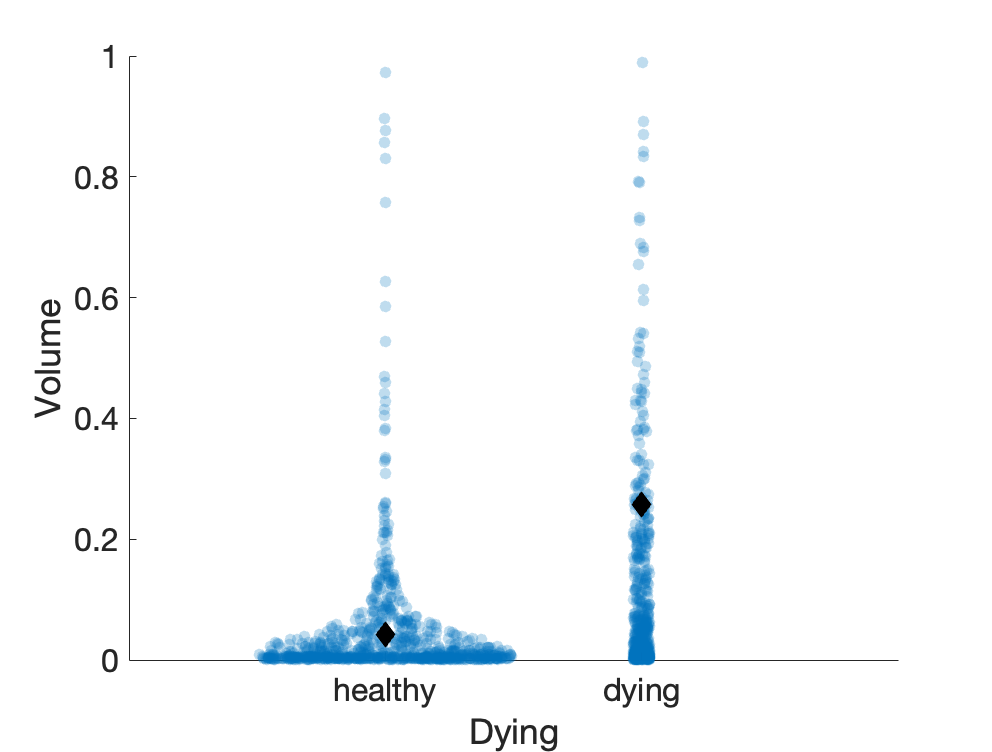

mmfig;
laII = cellT.Type == "II";

laHealth = cellT.Health == "healthy";
x = cellT.LysMeanVol(laII & laHealth);


Incorrect number or types of inputs or outputs for function isnan.

Error in ranksum (line 65)
x = x( ~isnan(x) );

% laHealth = cellT.Health == "early";
y = cellT.LysMeanVol(laII & ~laHealth);

gardnerAltmanPlot(x,y);

## Cell Volume Analysis

### Cell stats

cell_stats = groupsummary(cellT,"PlotSort",["min" "max"],"Volume")
disp(cell_stats)

## Visualize

### Total Lysosome Volume per Cell

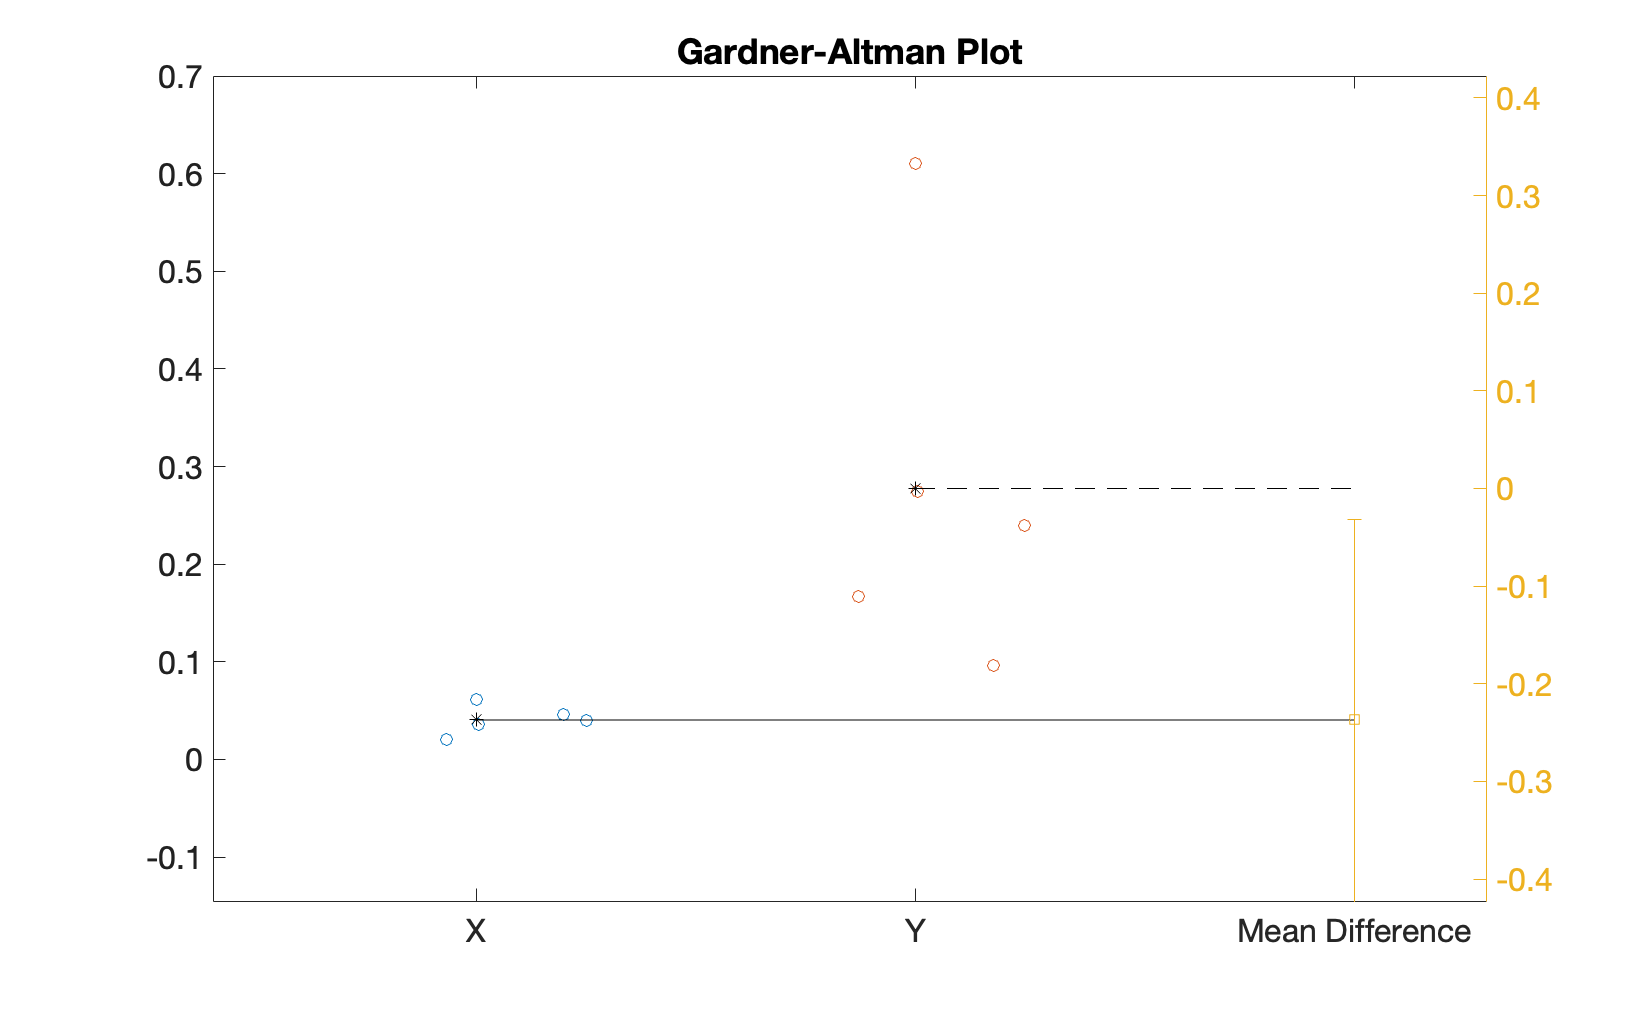

mmfig;

tiledlayout("horizontal")


g = cellT.PlotSort;
y = cellT.LysTotalVol;

hold on
boxchart(g,y,BoxFaceColor="#0072BD",Notch="off")
swarmchart(g,y, ...
    MarkerFaceColor="k", ...
    MarkerFaceAlpha=0.5, ...
    MarkerEdgeColor="k", ...
    XJitterWidth=0.25)
ylabel("Total Volume of Lysosome per cell (µm^3)")

### Ratio: Lysosome Total Volume to Cell Volume

mmfig;
tiledlayout("horizontal")

g = cellT.PlotSort;
y = cellT.LysCellRatio;

hold on
boxchart(g,y,BoxFaceColor="#0072BD",Notch="off")
swarmchart(g,y, ...
    MarkerFaceColor="k", ...
    MarkerFaceAlpha=0.5, ...
    MarkerEdgeColor="k", ...
    XJitterWidth=0.25)
ylabel("Ratio of Lys to Cell volume")